## Tutorial 2: Context Module

In this tutorial you will learn about the context decoding tools included with BrainStat. The context decoding module consists of three parts: genetic decoding, meta-analytic decoding and histological comparisons. First, we'll consider how to run the genetic decoding analysis. But before we get started, please note that this tutorial, alike the previous one, requires that you have BrainStat and all its dependencies installed. For more details see our installation guide. 

### Genetics

For genetic decoding we use the Allen Human Brain Atlas through the abagen toolbox. Note that, as abagen is only available in Python, we simply supply the genetic expression of pre-computed regions of interest with default parameters in the MATLAB toolbox. This should suffice for most use-cases, but for more specific use-cases we advise you to use the Python implementation of BrainStat. For a full list of supported parcellations see `help fetch_genetic_expression.`

[expression, gene_names] = fetch_genetic_expression('schaefer', 100);

Reading atlas from file. This may take a few minutes.


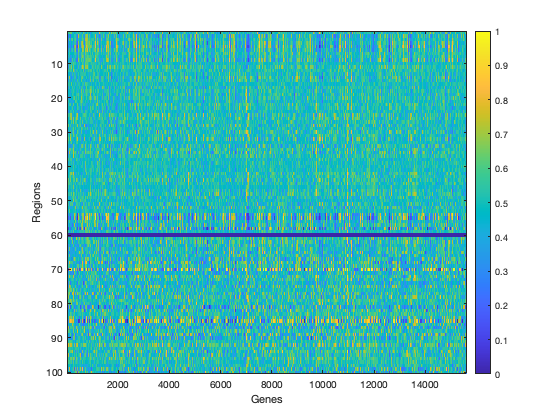

img = imagesc(expression);
xlabel('Genes');
ylabel('Regions');
colorbar;

The variable `expression` is a matrix containing the genetic expression of genes within each region of the atlas. These values will fall in the range [0, 1] where higher values represent higher expression. Some regions may return `NaN` values for all genes (e.g. see region 60 in the plot). This occurs when there are no samples within this region across all donors. The variable `gene_names` contains the names of each gene in the same order as the columns of `expression`.

### `Meta-Analytic Decoding`

To perform meta-analytic decoding, BrainStat uses precomputed Neurosynth maps. Here we test which terms are most associated with a map of cortical thickness. A simple example analysis can be run as follows. First, we will load some cortical thickness data and two cortical surfaces. The ABIDE dataset provides this data on the CIVET surface, so we will also load those surfaces. The surface decoder interpolates the data from the surface to the voxels in the volume that are in between the two input surfaces. Please be aware that this analysis may take several minutes to download and run.

mask = fetch_mask('civet41k');
thickness = fetch_abide_data('sites', 'PITT');
[correlation, feature] = surface_decoder(mean(thickness), ...
    'template', 'civet41k');
disp(correlation(1:3));

    0.3895
    0.3808
    0.3630



disp(feature(1:3));

    {'temporal'}    {'frontotemporal'}    {'pole'}



The variable `correlation `now contains the correlation values between the input map `mean(thickness)` and each of the neurosynth features. The corresponding feature names are stored in the variable `feature`. 

### Histology

For histological decoding we use microstructural profile covariance gradients, as first shown by [(Paquola et al, 2019, Plos Biology)](https://journals.plos.org/plosbiology/article?id=10.1371/journal.pbio.3000284),  computed from the BigBrain dataset. Firstly, lets download the MPC data and compute its gradients.

schaefer_400 = fetch_parcellation('fsaverage5' ,'schaefer', 400);

Reading from version 2
colortable with 201 entries read (originally Schaefer2018_400Parcels_7Networks)
Reading from version 2
colortable with 201 entries read (originally Schaefer2018_400Parcels_7Networks)



profiles = read_histology_profile('template', 'fsaverage5');
mpc = compute_mpc(profiles, schaefer_400);

Sorting data by smallest to largest number in the label! (labelmean.m)


gm = compute_histology_gradients(mpc);

The variable `profiles` now contains histological profiles sampled at 50 different depths across the cortex, `mpc` contains the covariance of these profiles, and `gm` contains their gradients. Depending on your use-case, each of these variables could be of interest, but for purposes of this tutorial we'll  plot the gradients to the surface with BrainSpace. For details on what the GradientMaps class, `gm`, contains please consult the BrainSpace documentation.

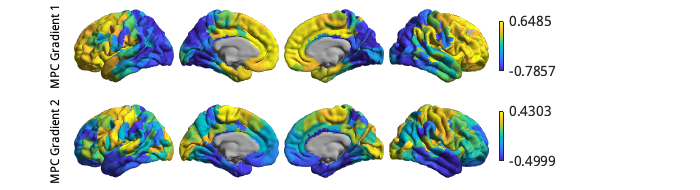

[surface_left, surface_right] = fetch_template_surface('fsaverage5');
vertexwise_gradients = parcel2full(gm.gradients{1}(:,1:2), schaefer_400);
vertexwise_gradients(isnan(vertexwise_gradients)) = inf; 

obj = plot_hemispheres(vertexwise_gradients, ...
    {surface_left, surface_right}, ...
    'labeltext', {'MPC Gradient 1', 'MPC Gradient 2'});
obj.colormaps([parula; .7 .7 .7])
pretty_plot(obj);

Note that we no longer use the y-axis regression used in [(Paquola et al., 2019, Plos Biology)](https://journals.plos.org/plosbiology/article?id=10.1371/journal.pbio.3000284), as such the first gradient becomes an anterior-posterior- gradient.

### Resting-State Contextualization

Lastly, BrainStat provides contextualization using resting-state fMRI markers: specifically, with the Yeo functional networks [(Yeo et al., 2011, Journal of Neurophysiology)](https://www.ncbi.nlm.nih.gov/pmc/articles/PMC3174820/), a clustering of resting-state connectivity, and the functional gradients [(Margulies et al., 2016, PNAS)](https://www.pnas.org/content/113/44/12574), a lower dimensional manifold of resting-state connectivity. 

Lets first have a look at contextualization of cortical thickness using the Yeo networks. We'll use some of the sample cortical thickness data included with BrainSpace, and see what its mean is within each Yeo network. 

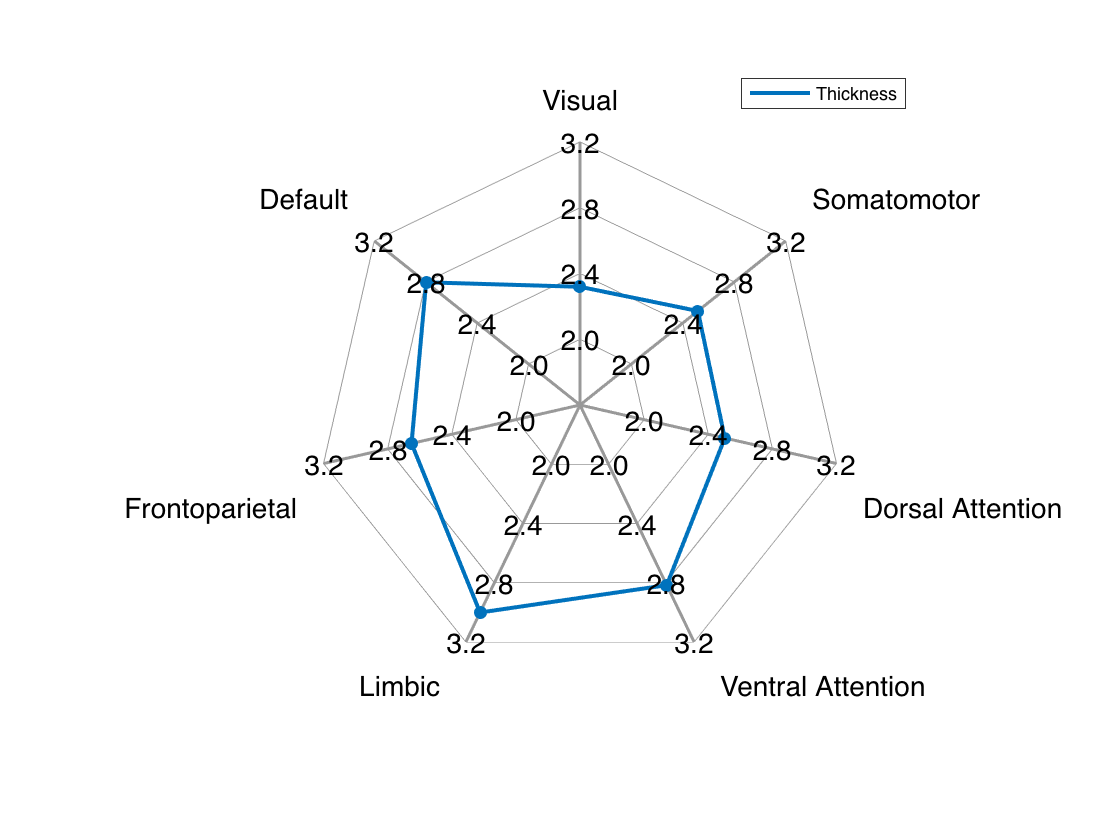

% Load cortical thickness
[thickness_left, thickness_right] = load_marker('thickness');
thickness = [thickness_left; thickness_right];

% Load Yeo networks
yeo_7_networks = fetch_parcellation('fslr32k', 'yeo', 7);
[network_names, colormap] = fetch_yeo_networks_metadata(7);

% Get mean intensity within yeo networks
mean_thickness = full2parcel(thickness', yeo_7_networks)';

% Plot
figure; 
s = spider_plot_class(mean_thickness, ...
    'AxesLabels', cellstr(network_names)', ...;
    'AxesLimits', [2; 3.2] .* ones(2,7), ...
    'AxesFontSize', 14, ...
    'LabelFontSize', 14, ...
    'LegendLabels', {'Thickness'}); 

Here we can see that, on average, the somatomotor/visual cortices have low cortical thickness whereas the default/limbic cortices have high thickness. 

Next, lets have a look at how cortical thickness relates to the first functional gradient which describes a sensory-transmodal axis in the brain. First lets plot the first few gradients.

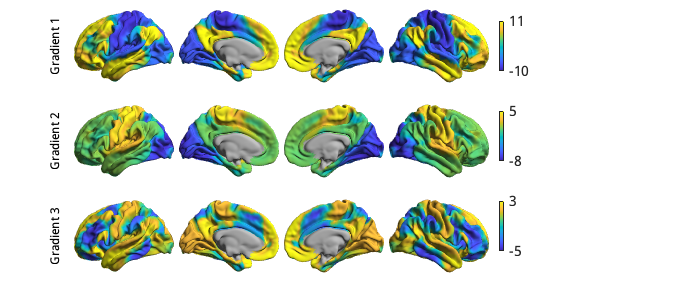

functional_gradients = fetch_gradients('fslr32k', 'margulies2016');
gradients_plot = functional_gradients;
gradients_plot(isnan(gradients_plot)) = -inf;

[surface_left, surface_right] = fetch_template_surface('fslr32k');

obj = plot_hemispheres(...
    gradients_plot(:,1:3), ...
    {surface_left, surface_right}, ...
    'LabelText', "Gradient " + (1:3));

obj.colormaps([.7 .7 .7; parula])
obj.colorlimits([-10, 11; -8, 5; -5, 3])

pretty_plot(obj)

There are many ways to compare these gradients to cortical markers such as cortical thickness. In general, we recommend using corrections for spatial autocorrelation which are implemented in BrainSpace. We'll show a correction with spin test in this tutorial; for other methods and further details please consult the BrainSpace tutorials. 

In a spin test we compare the empirical correlation between the gradient and the cortical marker to a distribution of correlations derived from data rotated across the cortical surface. The p-value then depends on the percentile of the empirical correlation within the permuted distribution. 

[sphere_left, sphere_right] = load_conte69('spheres');

% Note: we generally recommend running >=1000 permutations. For purposes
% of this tutorial we will only run 100.
thickness_permuted = spin_permutations( ...
    {thickness_left, thickness_right}, ...
    {sphere_left, sphere_right}, 100, ...
    'random_state', 2021); 

Running Spin Permutation


thickness_permuted_full = squeeze( ...
    [thickness_permuted{1}; thickness_permuted{2}]);
r_empirical = corr(thickness, functional_gradients(:, 1), ...
    'rows', 'pairwise');
r_permuted = corr(thickness_permuted_full, functional_gradients(:, 1), ...
    'rows', 'pairwise');

% Significance depends on whether we do a one-tailed or two-tailed test.
% If one-tailed it depends on in which direction the test is. 
p_value_right_tailed = mean(r_empirical > r_permuted);
p_value_left_tailed = mean(r_empirical < r_permuted);
p_value_two_tailed = min(p_value_right_tailed, p_value_left_tailed) * 2; 

fprintf(['The two-tailed p-value for the correlation between ' ...
    'cortical thickness and \n gradient 1 is %0.2g.\n'], ...
    p_value_two_tailed);

The two-tailed p-value for the correlation between cortical thickness and 
 gradient 1 is 0.04.


That concludes the tutorials of BrainStat. If anything is unclear, or if you think you've found a bug, please post it to the [Issues page of our Github](https://github.com/MICA-MNI/BrainStat/issues). 

Happy BrainStating!

function pretty_plot(obj)
    % Makes the BrainSpace plots prettier inside live scripts. 
    obj.handles.figure.Units = 'pixels';
    set(obj.handles.axes, 'Units', 'pixels')
    set(obj.handles.colorbar, 'Units', 'pixels');
    obj.handles.figure.Position = [1, 1, 700, size(obj.data, 2) * 95];
    set(obj.handles.text, 'FontSize', 12);
    
    for jj = 1:size(obj.data, 2) % variates
        obj.handles.colorbar(jj).Position = [...
            500, ...
            30 + (size(obj.data, 2) * 95) - 10 - jj*90, ...
            5, ...
            50];
        for ii = 1:4 % views
            obj.handles.axes(jj, ii).Position = [...
                75 + (ii-1)*105, ...
                (size(obj.data, 2) * 95) - jj*95, ...
                100, ...
                100];
        end
    end
end